clear all; close all; clc

## Lab 5

*Name: Joshua Yap*

*Lab Partner: Dane Thorn*

    In this lab, we import and explore simulated LHC data.

h5disp('higgs_100000_pt_250_500.h5')

HDF5 higgs_100000_pt_250_500.h5 
Group '/' 
    Dataset 'higgs_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp('qcd_100000_pt_250_500.h5')

HDF5 qcd_100000_pt_250_500.h5 
Group '/' 
    Dataset 'qcd_100000_pt_250_500' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


dataQCD = h5read('qcd_100000_pt_250_500.h5','/qcd_100000_pt_250_500')';
dataHiggs = h5read("higgs_100000_pt_250_500.h5","/higgs_100000_pt_250_500")';

The data is arranged in 14 columns, each one corresponding to a variable. With reference to the literature, the table below gives a brief description of each variable.

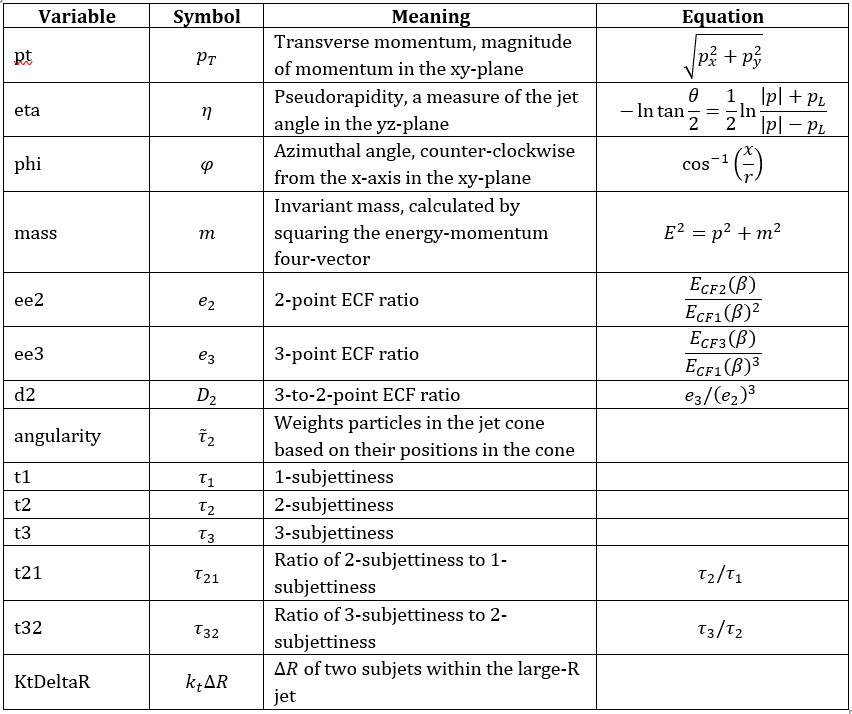

N-subjettiness is a measure of the degree to which radiation from a jet is aligned along N subjet axes.

Brief description of experiment

In order to make sense of the data we are given, we briefly outline key parts of the experiment in the Large Hadron Collider with the help of the diagram below.

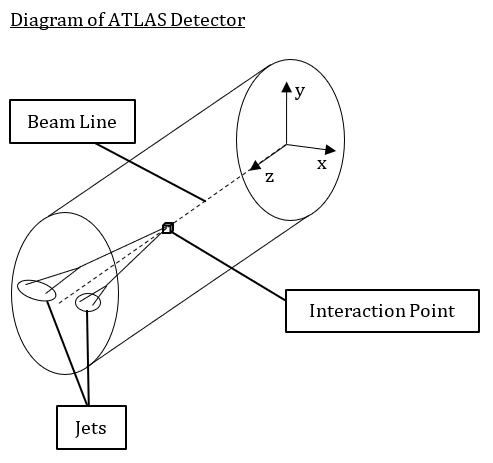

The LHC is a tube ring that accelerates particles along the beam line. The ATLAS detector is a cylinder in the ring that particles are made to collide in, at the interaction point. Upon collision, new particles may be created and split off from the beam line. Some new particles are short lived, and do not travel that far before decaying into other particles, which then hit the detector as jets. Based on the characteristics of the jet (particle grouping, mass, angle, etc.), experimenters can trace its path back to where the particle decayed and determine its mass. Many of the jet characteristics are variables given to us in the data. The coordinate system used gives us the angles as defined below.

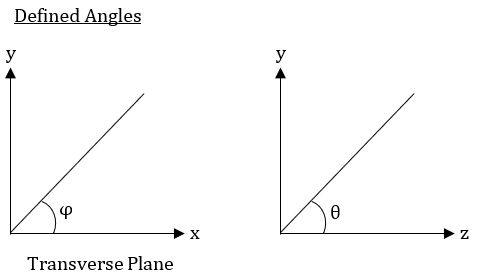

$\varphi$ is the azimuthal angle about the z-axis and $\theta$ is the polar angle.

With a basic idea of what is going on in the experiment, we make a few initial plots to see if there are any obvious correlations between variables.

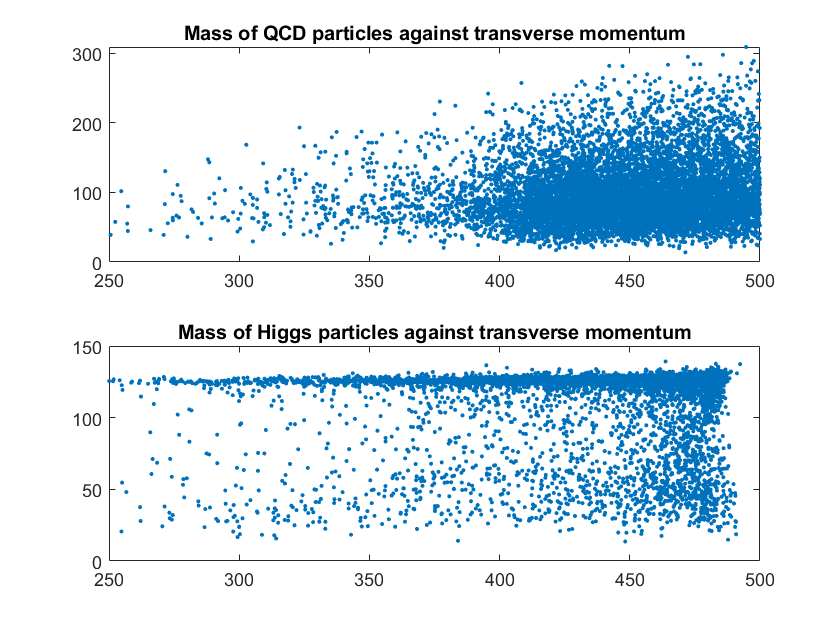

% Save QCD data in variables
ptQCD = dataQCD(:,1);
etaQCD = dataQCD(:,2);
phiQCD = dataQCD(:,3);
massQCD = dataQCD(:,4);
ee2QCD = dataQCD(:,5);
ee3QCD = dataQCD(:,6);
d2QCD = dataQCD(:,7);
angQCD = dataQCD(:,8);
t1QCD = dataQCD(:,9);
t2QCD = dataQCD(:,10);
t3QCD = dataQCD(:,11);
t21QCD = dataQCD(:,12);
t32QCD = dataQCD(:,13);
KtDeltaRQCD = dataQCD(:,14);
% Save Higgs data in variables
ptHiggs = dataHiggs(:,1);
etaHiggs = dataHiggs(:,2);
phiHiggs = dataHiggs(:,3);
massHiggs = dataHiggs(:,4);
ee2Higgs = dataHiggs(:,5);
ee3Higgs = dataHiggs(:,6);
d2Higgs = dataHiggs(:,7);
angHiggs = dataHiggs(:,8);
t1Higgs = dataHiggs(:,9);
t2Higgs = dataHiggs(:,10);
t3Higgs = dataHiggs(:,11);
t21Higgs = dataHiggs(:,12);
t32Higgs = dataHiggs(:,13);
KtDeltaRHiggs = dataHiggs(:,14);
% Plot
figure
subplot(2,1,1)
plot(ptQCD(1:10000),massQCD(1:10000),'.')
title('Mass of QCD particles against transverse momentum')
subplot(2,1,2)
plot(ptHiggs(1:10000),massHiggs(1:10000),'.')
title('Mass of Higgs particles against transverse momentum')

- Note differences between Higgs and QCD plots

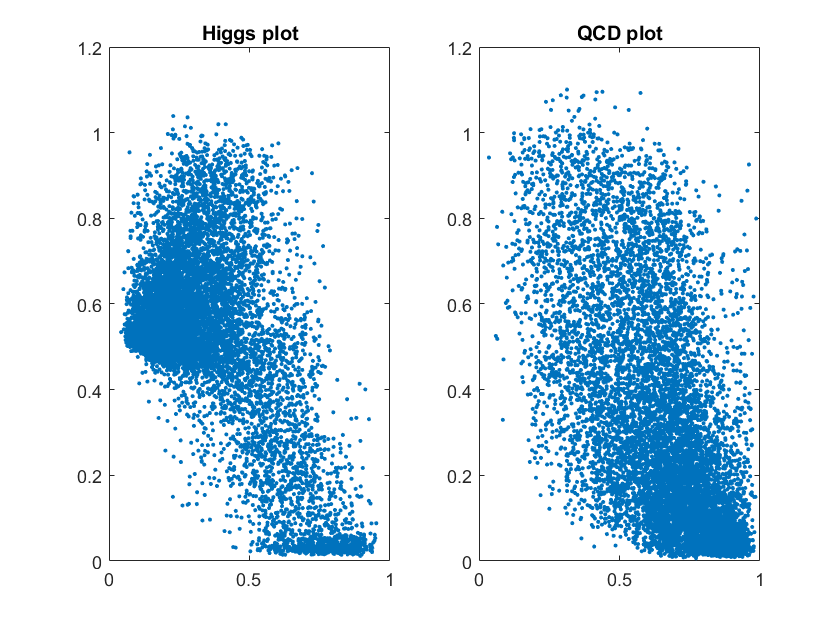

figure
subplot(1,2,1)
plot(t21Higgs(1:10000),KtDeltaRHiggs(1:10000),'.')
title('Higgs plot')
subplot(1,2,2)
plot(t21QCD(1:10000),KtDeltaRQCD(1:10000),'.')
title('QCD plot')